# UAV Scenario Tutorial

Create a scenario to simulate unmanned aerial vehicle (UAV) flights between a set of buildings. The example demonstrates updating the UAV pose in open-loop simulations. Use the UAV scenario to visualize the UAV flight and generate simulated point cloud sensor readings.

## Introduction

To test autonomous algorithms, a UAV scenario enables you to generate test cases and generate sensor data from the environment. You can specify obstacles in the workspace, provide trajectories of UAVs in global coordinates, and convert data between coordinate frames. The UAV scenario enables you to visualize this information in the reference frame of the environment.

## Create Scenario with Polygon Building Meshes

A `uavScenario` object is model consisting of a set of static obstacles and movable objects called platforms. Use `uavPlatform` objects to model fixed-wing UAVs, multirotors, and other objects within the scenario. This example builds a scenario consisting of a ground plane and 11 buildings as by extruded polygons. The polygon data for the buildings is loaded and used to add polygon meshes.

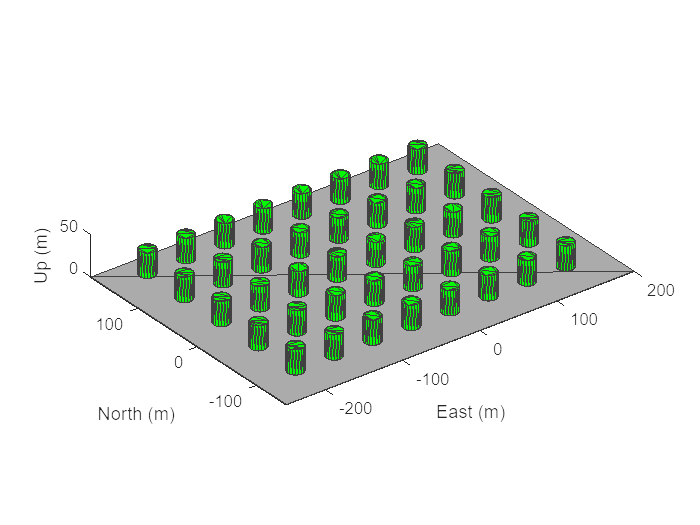

% Create the UAV scenario
scene = uavScenario("UpdateRate", 2, "ReferenceLocation", [75 -46 0]);

% Define colors
color.Gray = 0.651 * ones(1, 3);
color.Green = [0.3922 0.8314 0.0745];
color.Red = [1 0 0];

% Add a ground plane
addMesh(scene, "polygon", {[-250 -150; 200 -150; 200 180; -250 180], [-4 0]}, color.Gray);

% Load building polygons and flight data
load("buildingData.mat");
%load("flightData.mat");

% Set up grid dimensions for the cylinders
rows = 5;               % Number of rows in the grid
cols = 8;               % Number of columns in the grid
cylinderHeight = 30;    % Height of each cylinder
radius = 10;             % Radius of each cylinder
colorGreen = [0 1 0];   % RGB for green cylinders

% Define the starting x and y positions and the spacing between cylinders
xStart = -200;          % Starting x position
yStart = -100;          % Starting y position
xSpacing = 350 / (cols - 1);  % Horizontal spacing between cylinders
ySpacing = 250 / (rows - 1);  % Vertical spacing between cylinders

% Generate cylinder locations and add each to the scene
cylinderLocations = [];
for i = 0:(rows - 1)
    for j = 0:(cols - 1)
        % Calculate x and y positions for each cylinder
        xPos = xStart + j * xSpacing;
        yPos = yStart + i * ySpacing;
        
        % Store each cylinder's center location
        cylinderLocations = [cylinderLocations; xPos, yPos];
        
        % Add cylinder to the scene
        addMesh(scene, "Cylinder", {[xPos, yPos, radius], [0, cylinderHeight]}, colorGreen);
    end
end

% Define a minimum distance to avoid each cylinder (buffer distance)
minDistance = radius + 20;


% Adjust trajectory points in the position array to avoid cylinders
for idx = 1:size(position, 3)
    currentPos = position(:, :, idx);
    for k = 1:size(cylinderLocations, 1)
        % Calculate distance from the current position to each cylinder
        distance = norm(currentPos(1:2) - cylinderLocations(k, :));
        
        % If UAV is too close to a cylinder, adjust the path
        if distance < minDistance
            % Calculate vector to move away from the cylinder
            avoidDir = (currentPos(1:2) - cylinderLocations(k, :)) / distance;
            newPos = currentPos(1:2) + avoidDir * (minDistance - distance);
            position(1, 1, idx) = newPos(1); % Update x position
            position(1, 2, idx) = newPos(2); % Update y position
            % Optionally, modify the z position if altitude adjustments are needed
        end
    end
end

% Show the scenario
show3D(scene);
xlim([-250 200])
ylim([-150 180])
zlim([0 50])

## Define UAV Platform and Mount Sensor

You can define a `uavPlatform` in the scenario as a carrier of your sensor models and drive them through the scenario to collect simulated sensor data. You can associate the platform with various meshes, such as `fixedwing`, `quadrotor`, and `cuboid` meshes. You can define a custom mesh defined ones represented by vertices and faces. Specify the reference frame for describing the motion of your platform. 

Load flight data into the workspace and create a quadrotor platform using an NED reference frame. Specify the initial position and orientation based on loaded flight log data. The configuration of the UAV body frame orients the *x*-axis as forward-positive, the *y*-axis as right-positive, and the *z*-axis downward-positive.

load("flightData.mat")

% Set up platform
plat = uavPlatform("UAV",scene,"ReferenceFrame","NED", ...
    "InitialPosition",position(:,:,1),"InitialOrientation",eul2quat(orientation(:,:,1)));

Error using eul2quat
Expected eul to be an array with number of columns equal to 3.

Error in robotics.internal.validation.validateNumericMatrix (line 21)
validateattributes(M, {'single','double'}, {'nonempty','real','2d',varargin{:}}, ...

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('eul2quat', 'C:\Program Files\MATLAB\R2022a\toolbox\shared\robotics\robotutils\eul2quat.m', 34)" style="font-weight:


% Set up platform mesh. Add a rotation to orient the mesh to the UAV body frame.
updateMesh(plat,"quadrotor",{10},color.Red,[0 0 0],eul2quat([0 0 pi]))

You can choose to mount different sensors, such as the `insSensor`, `gpsSensor`, or `uavLidarPointCloudGenerator` System objects to your UAV. Mount a lidar point cloud generator and a `uavSensor` object that contains the lidar sensor model. Specify a mounting location of the sensor that is relative to the UAV body frame.

lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.3324099,...
    "ElevationLimits",[-20 20],"ElevationResolution",1.25,...
    "MaxRange",90,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0,0,-1]);

## Fly the UAV Platform Along Pre-Defined Trajectory and Collect Point Cloud Sensor Readings

Move the UAV along a pre-defined trajectory, and collect the lidar sensor readings along the way. This data could be used to test lidar-based mapping and localization algorithms. 

Preallocate the `traj` and `scatterPlot` line plots and then specify the plot-specific data sources. During the simulation of the `uavScenario`, use the provided `plotFrames` output from the scene as the parent axes to visualize your sensor data in the correct coordinate frames.

Visualize the scene.

[ax,plotFrames] = show3D(scene);

Update plot view for better visibility.

xlim([-250 200])
ylim([-150 180])
zlim([0 50])
view([-110 30])
axis equal
hold on

Create a line plot for the trajectory. First create the plot with `plot3`, then manually modify the data source properties of the plot. This improves performance of the plotting.

traj = plot3(nan,nan,nan,"Color",[1 1 1],"LineWidth",2);
traj.XDataSource = "position(:,2,1:idx+1)";
traj.YDataSource = "position(:,1,1:idx+1)";
traj.ZDataSource = "-position(:,3,1:idx+1)";

Create a scatter plot for the point cloud. Update the data source properties again.

colormap("jet")
pt = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
    "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(pt.Location(:,:,1),[],1)";
scatterplot.YDataSource = "reshape(pt.Location(:,:,2),[],1)";
scatterplot.ZDataSource = "reshape(pt.Location(:,:,3),[],1)";
scatterplot.CDataSource = "reshape(pt.Location(:,:,3),[],1) - min(reshape(pt.Location(:,:,3),[],1))";


Set up the simulation. Then, iterate through the positions and show the scene each time the lidar sensor updates. Advance the scene, move the UAV platform, and update the sensors.

setup(scene)

view([-89.2 84.2])

for idx = 0:size(position, 3)-1
    [isupdated,lidarSampleTime, pt] = read(lidar);
    if isupdated
        % Use fast update to move platform visualization frames.
        show3D(scene,"Time",lidarSampleTime,"FastUpdate",true,"Parent",ax);
        % Refresh all plot data and visualize.
        refreshdata
        drawnow limitrate
    end
    % Advance scene simulation time and move platform.
    advance(scene);
    move(plat,[position(:,:,idx+1),zeros(1,6),eul2quat(orientation(:,:,idx+1)),zeros(1,3)])
    % Update all sensors in the scene.
    updateSensors(scene)
end
hold off

% xlim([-250 200])
% ylim([-150 180])
% zlim([-17.8 30.0])


view([-89.2 84.2])

*Copyright 2020 The MathWorks, Inc.*